# CT Project (due 4/30)

by Brendan Harrington and Devon Mckeon

%% Helper Functions
function sino = forward_project(P, angles)
    n = size(P,1);
    sino = zeros(n, length(angles));
    for i = 1:length(angles)
        rotated = imrotate(P, -angles(i), 'crop');
        sino(:,i) = sum(rotated,2);
    end
end

function backproj = back_project(proj, angle, size_img)
    line = repmat(proj,1,size_img);
    backproj = imrotate(line, angle, 'crop');
end

function sino_filt = apply_ramp_filter(sino)
    N = size(sino,1);
    f = linspace(-0.5,0.5,N);
    ramp = abs(f)';
    
    sino_filt = zeros(size(sino));
    for i = 1:size(sino,2)
        temp = fftshift(fft(sino(:,i)));
        temp = temp .* ramp;
        temp = ifft(ifftshift(temp), 'symmetric');
        sino_filt(:,i) = temp;
    end
end

## Task 1

Calculate the fraction of photon energy measured after passing through an object with thickness 2 cm and linear attenuation coefficient 2.5 cm−1 .

### Answer

mu = 2.5; % cm^-1
thickness = 2; % cm
fraction_measured = exp(-mu * thickness);

fprintf('Fraction of photon energy measured: %.4f\n', fraction_measured);

Fraction of photon energy measured: 0.0067


## Task 2

At the chosen photon energy, aluminum has a mass attenuation coefficient of 0.2 cm2/g (density 2.7g/cm3 ) and lead 5.46 cm2/g (density 11.4g/cm3 ). What thickness of aluminum is equivalent in its attenuation to 1 mm lead? Based on these data, justify why you think we commonly use lead for shielding rather than aluminum.

### Answer

mu_rho_Al = 0.2; % cm^2/g
rho_Al = 2.7; % g/cm^3
mu_rho_Pb = 5.46; % cm^2/g
rho_Pb = 11.4; % g/cm^3

mu_Al = mu_rho_Al * rho_Al;
mu_Pb = mu_rho_Pb * rho_Pb;

thickness_Pb = 0.1; % cm (1 mm)
thickness_Al = (mu_Pb * thickness_Pb) / mu_Al;

fprintf('Equivalent Aluminum thickness: %.4f cm\n', thickness_Al);

Equivalent Aluminum thickness: 11.5267 cm


## Task 3

Use the phantom command to generate a 256 x 256 pixel modified Shepp-Logan target. Make an image of this target and be sure to use ‘axis image’ so the pixels are shown proportionally. Note that you have not been given spatial dimensions yet - use a pixel spacing of 1.5 mm in each direction. Use ‘colormap gray’ to use the grayscale color mapping and ‘colorbar’ to add a color bar annotation. Find and show an image of a real head CT online that you feel is comparable. Describe how features in this phantom may compare to a real head target.

### Answer

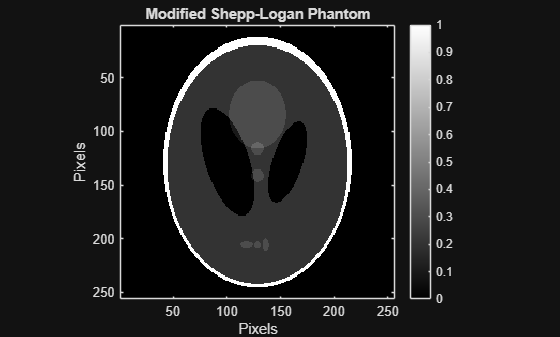

phantom_size = 256;
spacing = 1.5; % mm

P = phantom('Modified Shepp-Logan', phantom_size);

figure;
imagesc(P);
axis image;
colormap gray;
colorbar;
title('Modified Shepp-Logan Phantom');
xlabel('Pixels'); ylabel('Pixels');


% [Insert description of real CT image comparison here in report]

## Task 4

Write a function that implements forward projection to create a sinogram from the target over a chosen set of angles. First, run your function for an angle of 0 degrees, representing the projection from left-to-right (integrating along each row of the map), and plot the resulting projection as a function of detector location. Then calculate the complete sinogram using angles from 0:179 degrees in 1 degree increments. Show an image of the sinogram as a function of detector location (on the y-axis) and angle (on the x-axis). You may not use the radon command.

### Answer

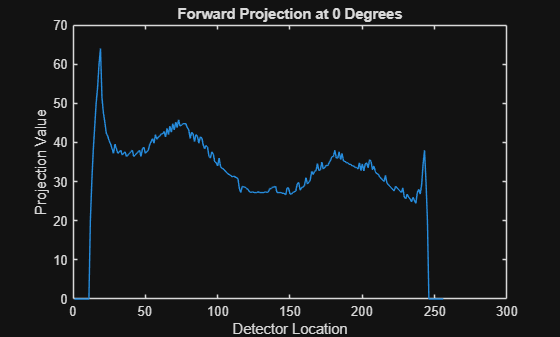

angles = 0:179;

sinogram = forward_project(P, angles);

% Single projection at 0 degrees
figure;
plot(sinogram(:,1));
xlabel('Detector Location'); ylabel('Projection Value');
title('Forward Projection at 0 Degrees');

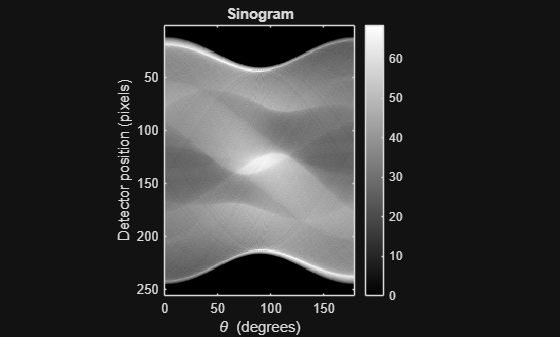


% Full sinogram
figure;
imagesc(angles, [], sinogram);
colormap gray;
colorbar;
axis image;
xlabel('\theta (degrees)'); ylabel('Detector position (pixels)');
title('Sinogram');

## Task 5

Identify at least two features from the original phantom target in your sinogram and describe how they correspond. You can add arrows or annotations if that helps your analysis.

### Answer

% [Add arrows/annotations in writeup]

## Task 6

Implement the back projection operator. First, demonstrate the backprojection of the data from 0 degrees – the result should be an image with the single line smeared horizontally across the spatial grid. Then complete the full backprojection of your data, integrating the result across data angles. Make an image of the result (colormap gray and colorbar), and compare your result to the original attenuation map – what is different about them? You may not use the iradon command.

### Answer

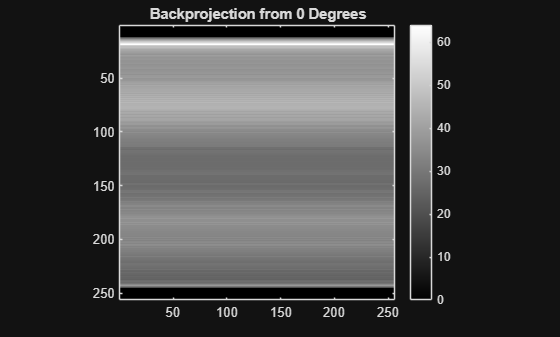

% Backproject single 0 degree line
backproj_single = back_project(sinogram(:,1), 0, phantom_size);

figure;
imagesc(backproj_single);
axis image;
colormap gray;
colorbar;
title('Backprojection from 0 Degrees');

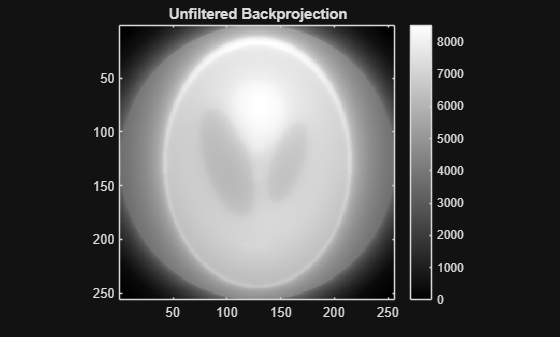


% Full backprojection
recon_backproj = zeros(phantom_size);
for i = 1:length(angles)
    recon_backproj = recon_backproj + back_project(sinogram(:,i), angles(i), phantom_size);
end

figure;
imagesc(recon_backproj);
axis image;
colormap gray;
colorbar;
title('Unfiltered Backprojection');


% [Describe differences vs original]

## Task 7

Implement a ramp filter you can apply to the sinogram before backprojection. First, plot the frequency response of your filter. Then show the sinogram before and after filtering, and your backprojected image using the filtered sinogram.

### Answer

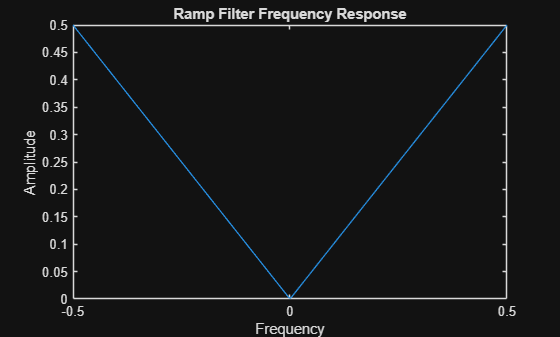

sinogram_filtered = apply_ramp_filter(sinogram);

% Frequency response of the ramp filter
N = size(sinogram,1);
f = linspace(-0.5, 0.5, N);
ramp_filter = abs(f);

figure;
plot(f, ramp_filter);
xlabel('Frequency'); ylabel('Amplitude');
title('Ramp Filter Frequency Response');

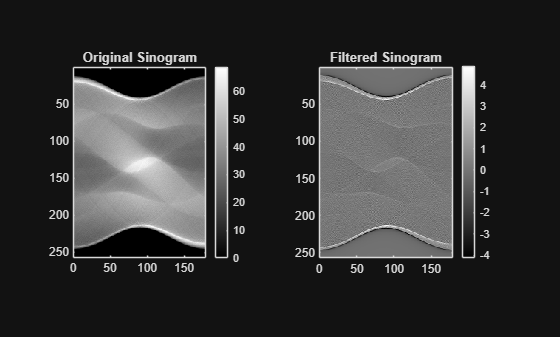


% Show filtered sinogram
figure;
subplot(1,2,1);
imagesc(angles, [], sinogram);
colormap gray;
colorbar;
title('Original Sinogram');
axis image;

subplot(1,2,2);
imagesc(angles, [], sinogram_filtered);
colormap gray;
colorbar;
title('Filtered Sinogram');
axis image;

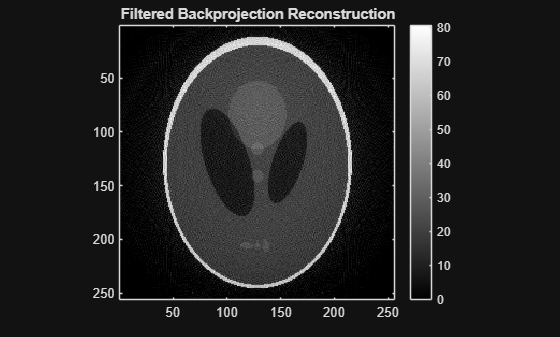


% Reconstruct using filtered backprojection
recon_filtered = zeros(phantom_size);
for i = 1:length(angles)
    recon_filtered = recon_filtered + back_project(sinogram_filtered(:,i), angles(i), phantom_size);
end

figure;
imagesc(recon_filtered);
axis image;
colormap gray;
colorbar;
clim([0, max(recon_filtered(:))]);
title('Filtered Backprojection Reconstruction');

## Task 8

What type of filter is this (e.g. low pass, high pass, bandpass, bandstop)? Briefly explain your answer.

### Answer

% [Answer: High-pass filter. Explanation in writeup]

## Task 9

 Explore what happens to your backprojected image as you reduce the number of projection angles acquired by a factor of 2, 4, and 6 (i.e. skipping angles to keep only every 2nd, 4th, or 6th). Show the resulting image for each case and describe the artifacts created.

### Answer

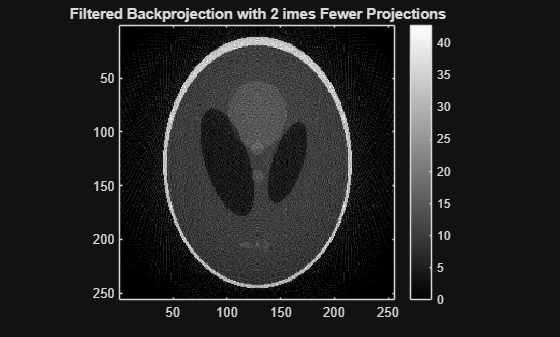

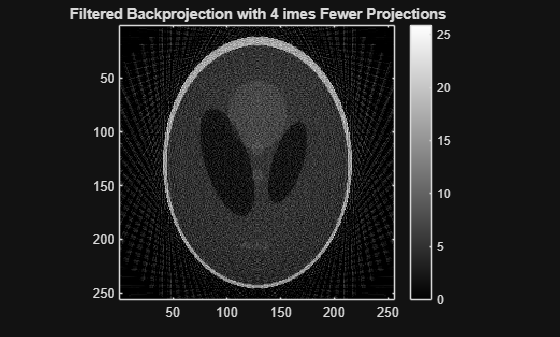

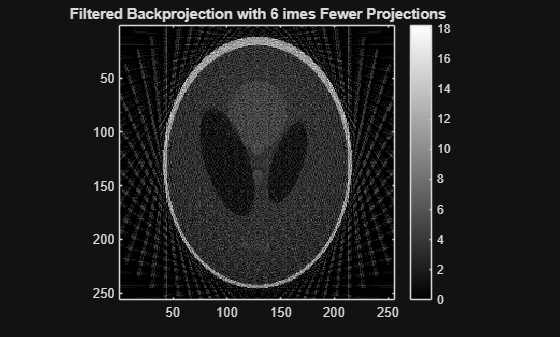

factors = [2,4,6];
for k = 1:length(factors)
    angles_reduced = 0:factors(k):179;
    sinogram_reduced = forward_project(P, angles_reduced);
    sinogram_reduced_filtered = apply_ramp_filter(sinogram_reduced);
    
    recon_reduced = zeros(phantom_size);
    for i = 1:length(angles_reduced)
        recon_reduced = recon_reduced + back_project(sinogram_reduced_filtered(:,i), angles_reduced(i), phantom_size);
    end
    
    figure;
    imagesc(recon_reduced);
    axis image;
    colormap gray;
    colorbar;
    clim([0, max(recon_reduced(:))]);
    title(sprintf('Filtered Backprojection with %d\times Fewer Projections', factors(k)));
end

## Task 10

Show the sinograms and your created filtered backprojection images from both the clean and noisy data

### Answer

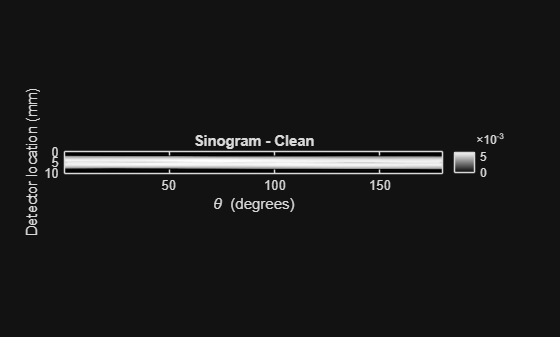

load('data/data_axes.mat');
data_clean = imread('data/data_clean.tif')';
data_noisy = imread('data/data_noisy.tif')';

figure;
imagesc(theta, l, data_clean);
colormap gray;
colorbar;
title('Sinogram - Clean');
xlabel('\theta (degrees)'); ylabel('Detector location (mm)');
axis image;


figure;
imagesc(theta, l, data_noisy);
colormap gray;
colorbar;
title('Sinogram - Noisy');
xlabel('\theta (degrees)'); ylabel('Detector location (mm)');
axis image;


% Filtered backprojection of clean data
recon_clean = zeros(length(l));
for i = 1:length(theta)
    filtered_data_clean = apply_ramp_filter(data_clean);
    recon_clean = recon_clean + back_project(filtered_data_clean(:,i), theta(i), length(l));
end

figure;
imagesc(recon_clean);
axis image;
colormap gray;
colorbar;
clim([0, max(recon_clean(:))]);
title('Filtered Backprojection - Clean Data');

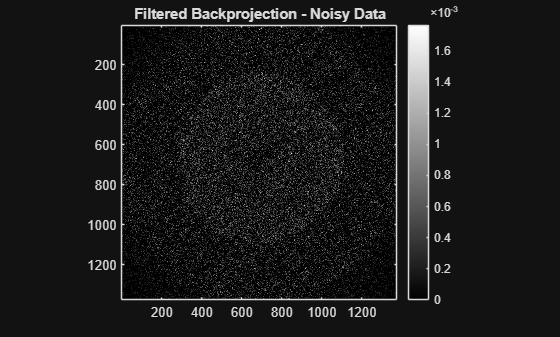


% Filtered backprojection of noisy data
recon_noisy = zeros(length(l));
for i = 1:length(theta)
    filtered_data_noisy = apply_ramp_filter(data_noisy);
    recon_noisy = recon_noisy + back_project(filtered_data_noisy(:,i), theta(i), length(l));
end

figure;
imagesc(recon_noisy);
axis image;
colormap gray;
colorbar;
clim([0, max(recon_noisy(:))]);
title('Filtered Backprojection - Noisy Data');

## Task 11

1 Apply a 2-D low pass filter of your choice to the noisy reconstructed image to reduce the effect of random noise and make it look more like the clean image. Show the resulting image. How does filter cutoff affect your result?

### Answer

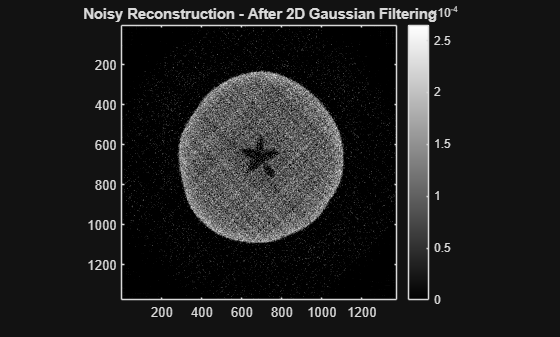

h = fspecial('gaussian', [15 15], 2);
recon_noisy_filtered = imfilter(recon_noisy, h, 'replicate');

figure;
imagesc(recon_noisy_filtered);
axis image;
colormap gray;
colorbar;
clim([0, max(recon_noisy_filtered(:))]);
title('Noisy Reconstruction - After 2D Gaussian Filtering');


% [Describe effect of filter cutoff in writeup]

## Task 12

What is the most important thing that you learned from this lab exercise? What did you like/dislike the most about this lab exercise?

### Answer

% [Write brief summary about learning experience in report]